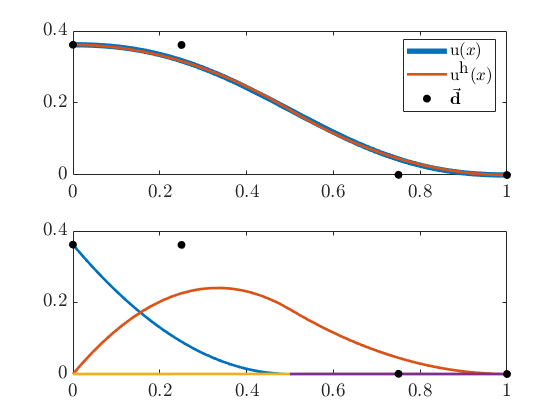

clear
close all

nElem = 2;
elemDegree = 2;
elemContinuity = 1;
doInterp = false;

if doInterp == true
    assert(elemContinuity == 0)
end

elemContinuity = [-1 repmat(elemContinuity,1,nElem-1) -1];

syms f(x) g h
f(x) = sin(x*2*pi)+cos(x*pi);
g = sym(0);
h = sym(0);

E = computeExactSolution(f,g,h);
FE = main(nElem, elemDegree, elemContinuity, doInterp, f, g, h);

figure
subplot(2,1,1)
setupAxes(gca);
hold on
fplot(E.U,[0 1],'LineWidth',4,"DisplayName","$$\textrm{u}(x)$$")
fplot(FE.U,[0 1],'LineWidth',2,"DisplayName","$$\textrm{u}^\textrm{h}(x)$$")
scatter(FE.Spline.nodes,FE.LinearSystem.d,"ko","filled","DisplayName","$$\vec{\textbf{d}}$$")
legend("Interpreter","latex")

subplot(2,1,2)
setupAxes(gca);
hold on
if doInterp == false
    N = FE.Spline.basis.functions;
    elemBases = [FE.Spline.decomposition.localExtractionSupportedSplineBases{:}];
    for ii = 1:length(N)
        suppElems = find(any(elemBases == ii,1));
        funDomain = FE.Spline.uniqueKnotsVector([suppElems(1) suppElems(end)+1]);
        fplot(N(ii) .* FE.LinearSystem.d(ii),funDomain,"LineWidth",2)
    end
    scatter(FE.Spline.nodes,FE.LinearSystem.d,'ko','filled')
    
else
    ELEMS = FE.Elements;
    bfun_id = [FE.Spline.decomposition.localExtractionSupportedSplineBases{:}];
    cmap = lines();
    for e = 1:length(ELEMS)
        funDomain = ELEMS(e).GDomain;
        x_xi = computeAffineMapping(ELEMS(e).LDomain,ELEMS(e).GDomain, symvar(ELEMS(e).LBasisFuns));
        N = ELEMS(e).LBasisFuns(x_xi);
        for n = 1:length(N)
            fplot(N(n) * ELEMS(e).GDOF(n),funDomain,"LineWidth",2,"Color",cmap(bfun_id(n,e),:))
        end
    end
    scatter(FE.Spline.nodes,FE.LinearSystem.d,'ko','filled')
end


A = double(FE.LinearSystem.K);
b = double(FE.LinearSystem.F);
sol = FE.LinearSystem.d;

c = cond(A)

c = 8.5497

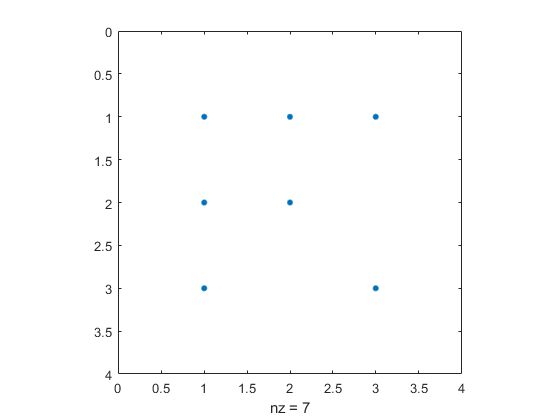


figure
spy(sparse(A))


err = double(computeError(E, FE, "Exact-Global", 0))

err = 0.0018

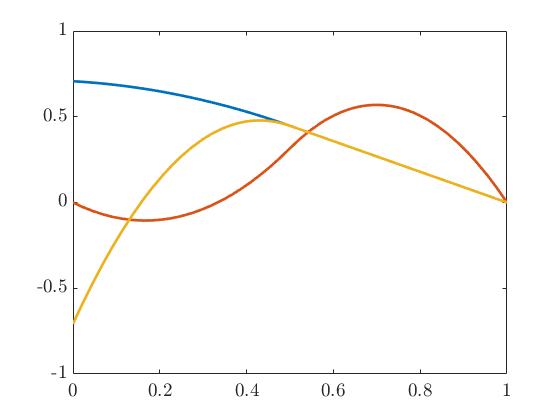

figure
ax = setupAxes(gca);
hold on
V = FE.Eigen.V;
for ii = 1:length(V)
    fplot(real(V(ii)),[0 1],'LineWidth',2,"ShowPoles","off","DisplayName","$$ \textrm{v}_{" + num2str(ii) + "} $$")
end
ax.BoxStyle = "full";
ax.ClippingStyle = "rectangle";

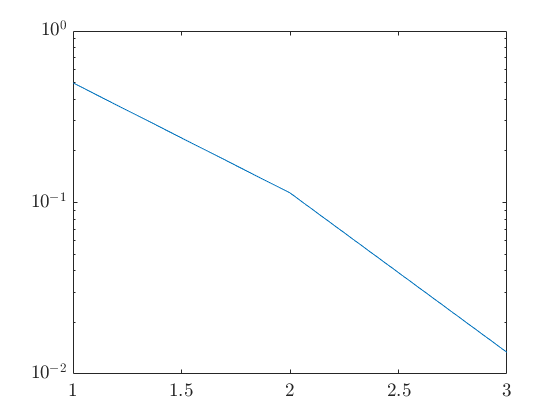


figure
plot(abs(FE.Eigen.coeff))
ax = setupAxes(gca);
ax.YScale = "log";


eigval = FE.Eigen.val;
eigvec = FE.Eigen.vec;
orth_V = zeros(length(eigval));
for v1 = 1:length(eigval)
    for v2 = 1:length(eigval)
        orth_V(v1,v2) = double(int(V(v1) * V(v2),[0 1]));   
    end
end
orth_V

orth_V =     0.2213    0.0491    0.0633
    0.0491    0.1067    0.0640
    0.0633    0.0640    0.1054


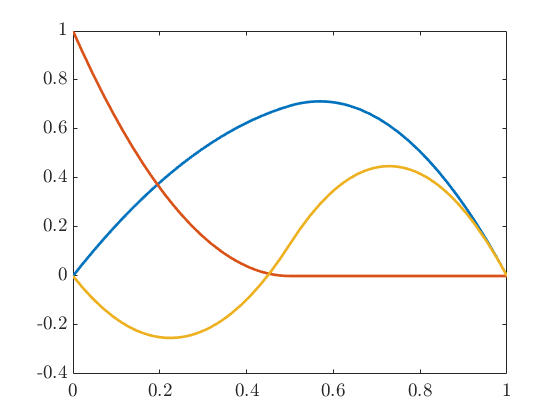

figure
ax = setupAxes(gca);
hold on
V = FE.Preconditioned.Eigen.V;
for ii = 1:length(V)
    fplot(real(V(ii)),[0 1],'LineWidth',2,"ShowPoles","off","DisplayName","$$ \textrm{v}_{" + num2str(ii) + "} $$")
end
ax.BoxStyle = "full";
ax.ClippingStyle = "rectangle";

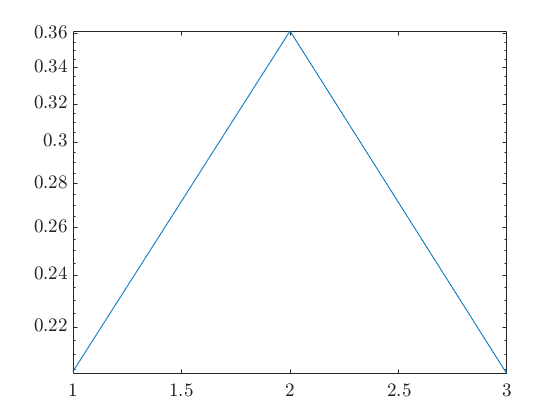


figure
plot(abs(FE.Preconditioned.Eigen.coeff))
ax = setupAxes(gca);
ax.YScale = "log";


eigval = FE.Preconditioned.Eigen.val;
eigvec = FE.Preconditioned.Eigen.vec;
orth_V = zeros(length(eigval));
for v1 = 1:length(eigval)
    for v2 = 1:length(eigval)
        orth_V(v1,v2) = double(int(V(v1) * V(v2),[0 1]));
    end
end
orth_V

orth_V =     0.2598    0.0398    0.0606
    0.0398    0.1000   -0.0260
    0.0606   -0.0260    0.0735


function ax = setupAxes(ax)
ax.Box = "on";
ax.TickLabelInterpreter = "latex";
ax.FontSize = 14;
end